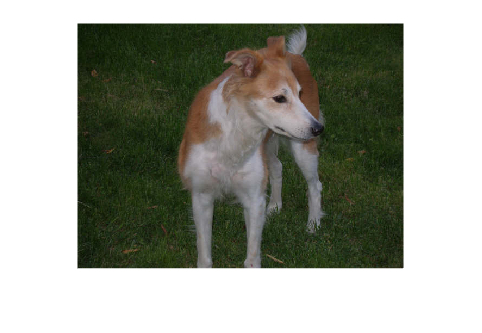

I=imread("Dog.jpg");
imshow(I)

% Split the image into its RGB channels
R = I(:, :, 1);
G = I(:, :, 2);
B = I(:, :, 3);

% Compute histograms for each channel
[counts_R, bins_R] = imhist(R);
[counts_G, bins_G] = imhist(G);
[counts_B, bins_B] = imhist(B);

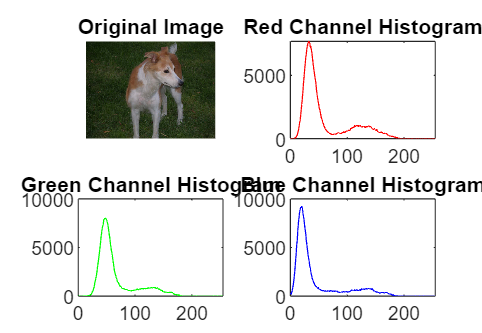

% Plot the original image
subplot(2, 2, 1);
imshow(I)
title('Original Image');

% Plot the histograms
subplot(2, 2, 2);
plot(bins_R, counts_R, 'r')
title('Red Channel Histogram');

subplot(2, 2, 3);
plot(bins_G, counts_G, 'g')
title('Green Channel Histogram');

subplot(2, 2, 4);
plot(bins_B, counts_B, 'b')
title('Blue Channel Histogram');

% Apply Sobel edge detection
edge_sobel = edge(rgb2gray(I), 'sobel');

% Apply Prewitt edge detection
edge_prewitt = edge(rgb2gray(I), 'prewitt');

% Apply Canny edge detection
edge_canny = edge(rgb2gray(I), 'canny');

% Define custom threshold values
low_threshold = 0.1; % Adjust as needed
high_threshold = 0.3; % Adjust as needed

% Apply Canny edge detection with custom thresholds
edge_canny_custom = edge(rgb2gray(I), 'canny', [low_threshold, high_threshold]);

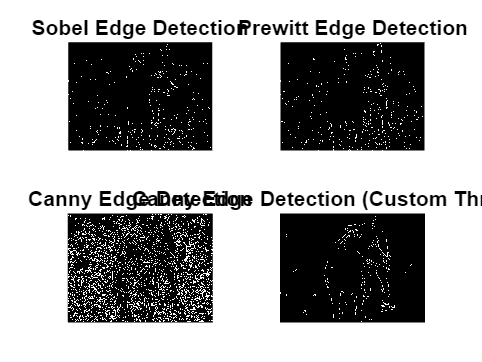

% Visualize the results
figure;
subplot(2, 2, 1);
imshow(edge_sobel)
title('Sobel Edge Detection');

subplot(2, 2, 2);
imshow(edge_prewitt)
title('Prewitt Edge Detection');

subplot(2, 2, 3);
imshow(edge_canny)
title('Canny Edge Detection');

subplot(2, 2, 4);
imshow(edge_canny_custom)
title('Canny Edge Detection (Custom Thresholds)');

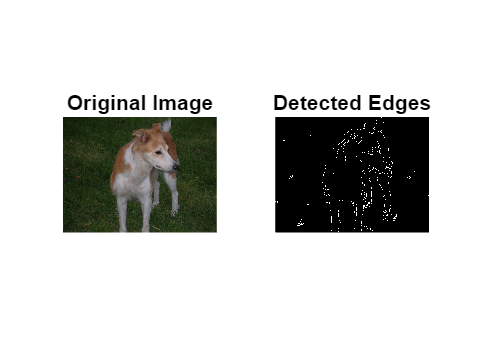

% Visualize the original image and detected edges for comparison
figure;
subplot(1, 2, 1);
imshow(I)
title('Original Image');

subplot(1, 2, 2);
imshow(edge_canny_custom)
title('Detected Edges');

% Save MATLAB script
script_filename = 'image_processing_script.m';
save(script_filename);

% Save figures
saveas(gcf, 'original_image_and_histograms.png'); % Save the figure as a .png image file


% Save computed histograms
save('computed_histograms.png', 'counts_R', 'bins_R', 'counts_G', 'bins_G', 'counts_B', 'bins_B');


